## NTN-TDL channel

simParameters.CarrierFrequency = 2.18e9; %19e9; % 2.18e9;                  % Carrier frequency (in Hz)
simParameters.SatelliteAltitude = 600000;

simParameters.ElevationAngle = 50;                     % Elevation angle (in degrees)
simParameters.MobileSpeed = 5*1000/3600;               % Speed of mobile terminal (in m/s)
simParameters.MobileAltitude = 0;

ue = nrCarrierConfig;
ue.NSizeGrid = 11;          % Bandwidth in number of resource blocks (52RBs at 15kHz SCS for 10MHz BW)
ue.SubcarrierSpacing = 30;  % 15, 30, 60, 120, 240 (kHz)
ue.CyclicPrefix = 'Normal'; % 'Normal' or 'Extended'

waveformInfo = nrOFDMInfo(ue);
simParameters.SampleRate = waveformInfo.SampleRate;
c = physconst("lightspeed");
satelliteDopplerShift = dopplerShiftCircularOrbit( ...
    simParameters.ElevationAngle,simParameters.SatelliteAltitude, ...
    simParameters.MobileAltitude,simParameters.CarrierFrequency);

nTxAnts = 1;  % Number of transmit antennas
nRxAnts = 1;  % Number of receive antennas
nLayers = min(nTxAnts,nRxAnts);

channel = nrTDLChannel;
channel.DelayProfile = 'NTN-TDL-D';
channel.DelaySpread = 30e-9;
channel.SatelliteDopplerShift = satelliteDopplerShift;
channel.MaximumDopplerShift = simParameters.MobileSpeed*simParameters.CarrierFrequency/c;
% channel.MaximumDopplerShift = 0;
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;
% channel.Seed = 5;
% Set channel sample rate
ofdmInfo = nrOFDMInfo(ue);
channel.SampleRate = ofdmInfo.SampleRate;

% Get the maximum delay of the channel
% chInfo = info(channel);
% maxChDelay = chInfo.MaximumChannelDelay;
chInfo = info(channel);
maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + ...
    chInfo.ChannelFilterDelay;

% Reset random generator for reproducibility
rng('default');

% Create a slot-wise resource grid empty grid
txGrid = nrResourceGrid(ue,nTxAnts);

txGrid1 = ones(size(txGrid));
[txWaveform1,~] = nrOFDMModulate(ue,txGrid1);
txWaveform1 = [txWaveform1; zeros(maxChDelay, size(txWaveform1,2))];


### Check the effective channel when we compensate sample-wise

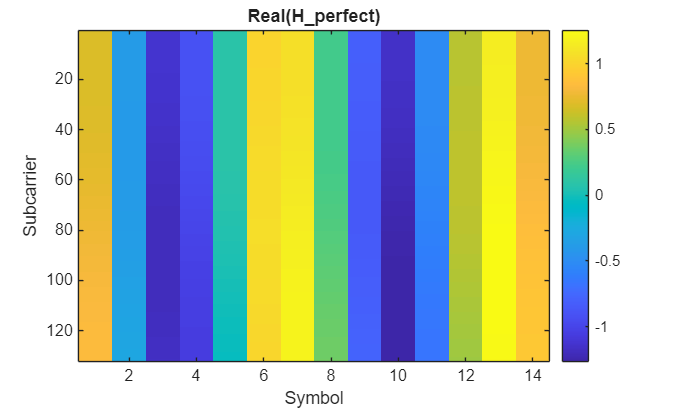

reset(channel);
% sample-wise Doppler precompensate
t = (0:size(txWaveform1,1)-1)'/simParameters.SampleRate;
txWaveform2 = txWaveform1.*exp(1j*2*pi*(-satelliteDopplerShift)*t);

[rxWaveform2,pathGains] = channel(txWaveform2);
pathFilters = getPathFilters(channel);
offset = nrPerfectTimingEstimate(pathGains,pathFilters);
rxGrid2 = nrOFDMDemodulate(ue,rxWaveform2(1+offset:end,:));
hEstPerfect2 = nrPerfectChannelEstimate(ue,pathGains,pathFilters,offset);    

figure; imagesc(real(hEstPerfect2)); colorbar; title('Real(H\_perfect)')
xlabel('Symbol'); ylabel('Subcarrier');

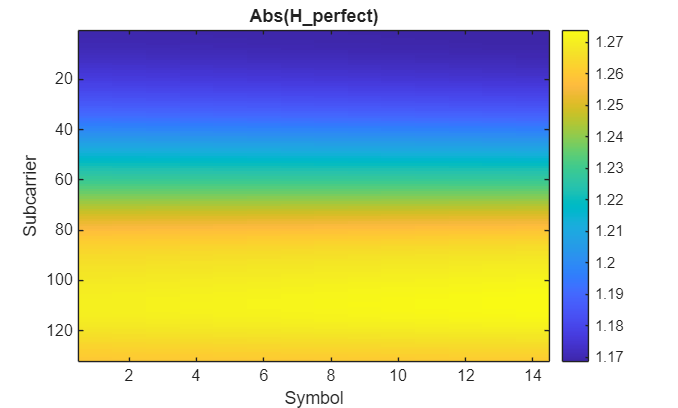

figure; imagesc(abs(hEstPerfect2)); colorbar; title('Abs(H\_perfect)')
xlabel('Symbol'); ylabel('Subcarrier');

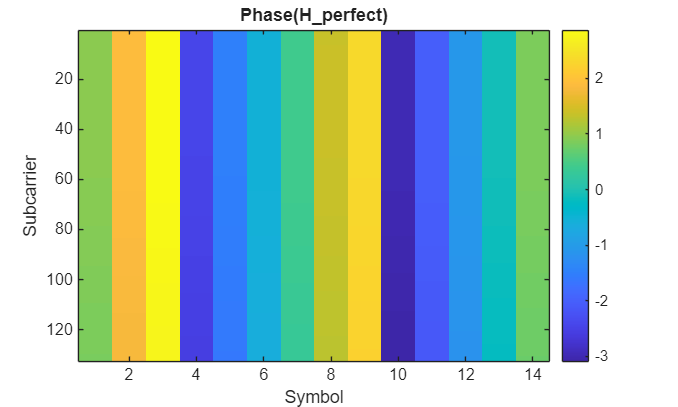

figure; imagesc(angle(hEstPerfect2)); colorbar; title('Phase(H\_perfect)')
xlabel('Symbol'); ylabel('Subcarrier');

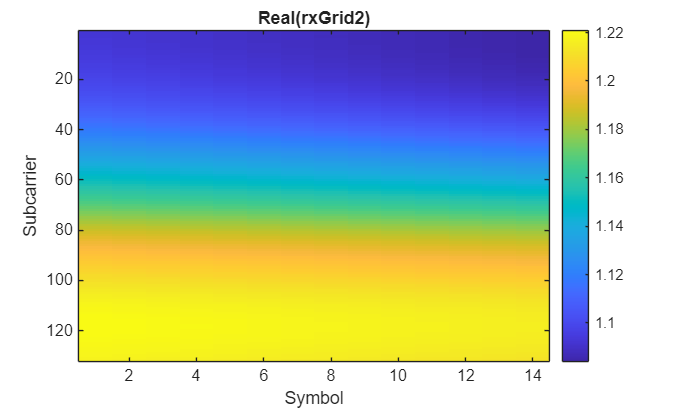

figure; imagesc(real(rxGrid2)); colorbar; title('Real(rxGrid2)')
xlabel('Symbol'); ylabel('Subcarrier');

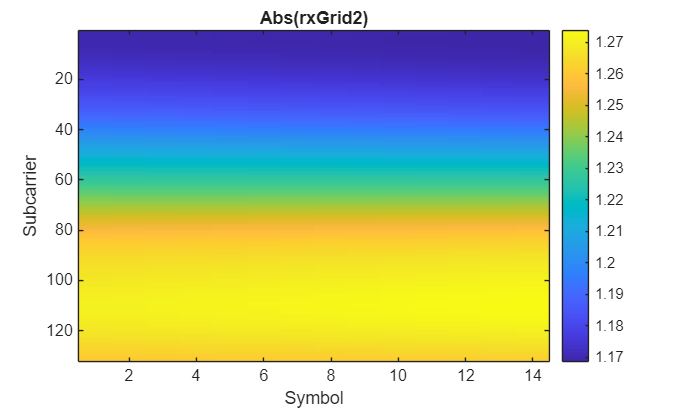

figure; imagesc(abs(rxGrid2)); colorbar; title('Abs(rxGrid2)')
xlabel('Symbol'); ylabel('Subcarrier');

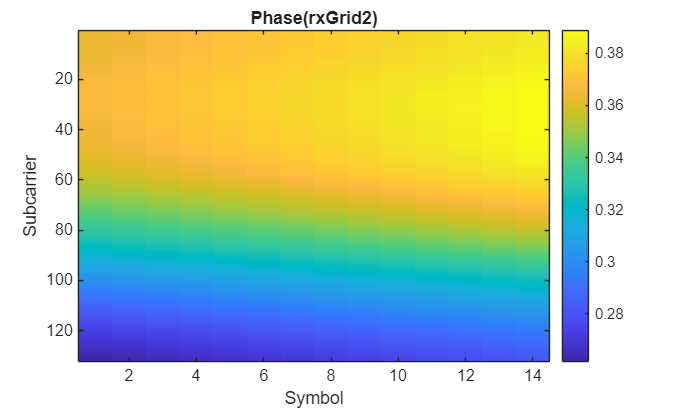

figure; imagesc(angle(rxGrid2)); colorbar; title('Phase(rxGrid2)')
xlabel('Symbol'); ylabel('Subcarrier');

## Domain 2

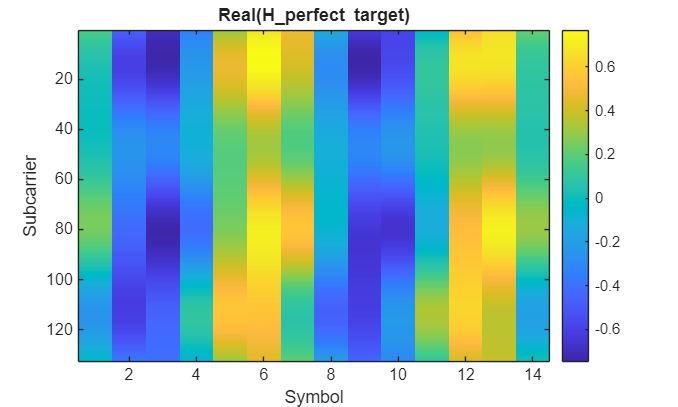

simParameters_target.CarrierFrequency = 2.18e9; %19e9; % 2.18e9;                  % Carrier frequency (in Hz)
simParameters_target.SatelliteAltitude = 600000;

simParameters_target.ElevationAngle = 50;                     % Elevation angle (in degrees)
simParameters_target.MobileSpeed = 5*1000/3600;               % Speed of mobile terminal (in m/s)
simParameters_target.MobileAltitude = 0;

ue_target = nrCarrierConfig;
ue_target.NSizeGrid = 11;          % Bandwidth in number of resource blocks (52RBs at 15kHz SCS for 10MHz BW)
ue_target.SubcarrierSpacing = 30;  % 15, 30, 60, 120, 240 (kHz)
ue_target.CyclicPrefix = 'Normal'; % 'Normal' or 'Extended'

waveformInfo_target = nrOFDMInfo(ue_target);
simParameters_target.SampleRate = waveformInfo_target.SampleRate;
c = physconst("lightspeed");
satelliteDopplerShift_target = dopplerShiftCircularOrbit( ...
    simParameters_target.ElevationAngle,simParameters_target.SatelliteAltitude, ...
    simParameters_target.MobileAltitude,simParameters_target.CarrierFrequency);

nTxAnts = 1;  % Number of transmit antennas
nRxAnts = 1;  % Number of receive antennas
nLayers = min(nTxAnts,nRxAnts);

channel_target = nrTDLChannel;
channel_target.DelayProfile = 'NTN-TDL-A';
channel_target.DelaySpread = 350e-9;
channel_target.SatelliteDopplerShift = satelliteDopplerShift_target;
channel_target.MaximumDopplerShift = simParameters_target.MobileSpeed*simParameters_target.CarrierFrequency/c;
% channel.MaximumDopplerShift = 0;
channel_target.NumTransmitAntennas = nTxAnts;
channel_target.NumReceiveAntennas = nRxAnts;
% channel.Seed = 5;
% Set channel sample rate
ofdmInfo = nrOFDMInfo(ue_target);
channel_target.SampleRate = ofdmInfo.SampleRate;

% Get the maximum delay of the channel
% chInfo = info(channel);
% maxChDelay = chInfo.MaximumChannelDelay;
chInfo = info(channel_target);
maxChDelay = ceil(max(chInfo.PathDelays*channel_target.SampleRate)) + ...
    chInfo.ChannelFilterDelay;

% Reset random generator for reproducibility
% rng('default');

% Create a slot-wise resource grid empty grid
txGrid = nrResourceGrid(ue_target,nTxAnts);

txGrid1 = ones(size(txGrid));
[txWaveform1,~] = nrOFDMModulate(ue_target,txGrid1);
txWaveform1 = [txWaveform1; zeros(maxChDelay, size(txWaveform1,2))];
t_target = (0:size(txWaveform1,1)-1)'/simParameters_target.SampleRate;
txWaveform2_target = txWaveform1.*exp(1j*2*pi*(-satelliteDopplerShift_target)*t_target);

[rxWaveform2_target,pathGains_target] = channel_target(txWaveform2_target);
pathFilters_target = getPathFilters(channel_target);
offset_target = nrPerfectTimingEstimate(pathGains_target,pathFilters_target);
rxGrid2_target = nrOFDMDemodulate(ue_target,rxWaveform2_target(1+offset_target:end,:));
hEstPerfect2_target = nrPerfectChannelEstimate(ue_target,pathGains_target,pathFilters_target,offset_target);

figure; imagesc(real(hEstPerfect2_target)); colorbar; title('Real(H\_perfect target)')
xlabel('Symbol'); ylabel('Subcarrier');

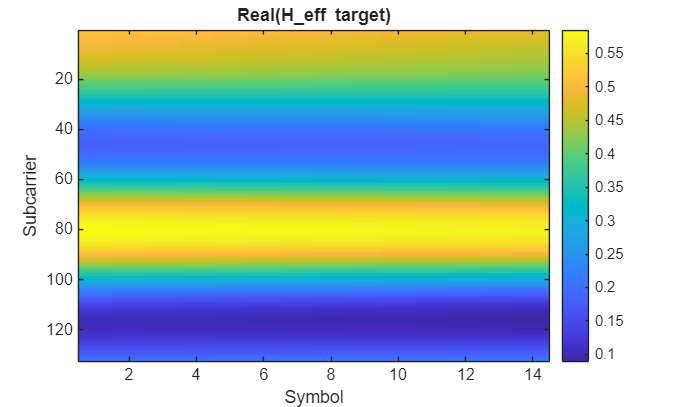

figure; imagesc(real(rxGrid2_target)); colorbar; title('Real(H\_eff target)')
xlabel('Symbol'); ylabel('Subcarrier');

## FDA Translation of H_eff source to H_eff target

function [amplitude_spectrum, phase_spectrum] = F_extract_DD(channel_grid)
% F_EXTRACT Converts Time-Freq channel to Delay-Doppler domain
% Input: 
%   channel_grid: 132 (Subcarriers) x 14 (Symbols) Complex Matrix
% Output:
%   amplitude_spectrum: Magnitude in Delay-Doppler (The "Style")
%   phase_spectrum: Phase in Delay-Doppler (The "Content")

    % 1. Transform Subcarriers (Frequency) -> Delay
    % We use IFFT along dimension 1 (Rows).
    % No shift needed here because delay is naturally 0 to Max.
    grid_delay = ifft(channel_grid, [], 1);
    
    % 2. Transform Symbols (Time) -> Doppler
    % We use FFT along dimension 2 (Columns).
    grid_delay_doppler_raw = fft(grid_delay, [], 2);
    
    % 3. Shift BOTH dimensions to Center
    % This moves (Delay=0, Doppler=0) to the middle of the matrix.
    grid_dd_shifted = fftshift(grid_delay_doppler_raw);
    
    % 4. Extract Amplitude and Phase
    amplitude_spectrum = abs(grid_dd_shifted);
    phase_spectrum = angle(grid_dd_shifted);

end

function [mixed_img] = fda_mix_pixels(source_img, target_img, win_h_px, win_w_px)
    % center: target
    % outer: source
    % 3. Calculate Center Coordinates
    [h, w] = size(source_img);
    cy = floor(h / 2) + 1;
    cx = floor(w / 2) + 1;   

    % 4. Determine Window Radius (Half-size)
    % We use floor to ensure we stay within integer indices
    % If you input 3 pixels, radius is 1 (Center +/- 1)
    r_h = floor(win_h_px / 2);
    r_w = floor(win_w_px / 2);

    % 5. Create the Mask
    % Initialize mask of zeros (use Source amplitude by default)
    mask = zeros(h, w);
    
    % Set the center region to 1 (use Target amplitude here)
    % We define the range explicitly around the center
    y_range = (cy - r_h) : (cy + r_h);
    x_range = (cx - r_w) : (cx + r_w);
    
    mask(y_range, x_range) = 1;
    
    % 6. Mix the Amplitudes
    % Logic: If mask is 1, take Target. If mask is 0, take Source.
    mixed_img = (mask .* target_img) + ((1 - mask) .* source_img); 
end

function [tf_grid] = F_inverse_DD(complex_dd)
% F_INVERSE_DD Converts Delay-Doppler grid back to Time-Freq grid
    % 1. Unshift Both Dimensions
    % Moves the Zero-Delay/Zero-Doppler peak from Center back to (1,1)
    grid_unshifted = ifftshift(complex_dd);
    
    % 2. Inverse Doppler -> Time (Dimension 2: Columns)
    % The Forward was FFT, so the Inverse is IFFT
    grid_delay_time = ifft(grid_unshifted, [], 2);
    
    % 3. Inverse Delay -> Frequency (Dimension 1: Rows)
    % The Forward was IFFT, so the Inverse is FFT
    tf_grid = fft(grid_delay_time, [], 1);
    
end

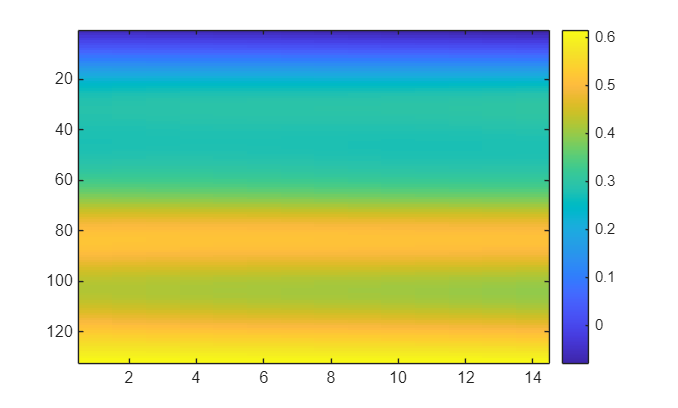

[A_amplitude_spectrum, A_phase_spectrum] = F_extract_DD(rxGrid2);
[B_amplitude_spectrum, B_phase_spectrum] = F_extract_DD(rxGrid2_target);
% imagesc(A_amplitude_spectrum); colorbar

% imagesc(B_amplitude_spectrum); colorbar
mix_AB = fda_mix_pixels(A_amplitude_spectrum, B_amplitude_spectrum, 3, 3);
    % center: B
    % outer: A
% imagesc(real(mix_AB)); colorbar
fft_mixed = mix_AB .* exp(1i * A_phase_spectrum);
adapted_image = F_inverse_DD(fft_mixed);
imagesc(real(adapted_image)); colorbar

## FDA Translate input and label of Source domain to target input

% source_domain = load('sampleWiseDoppler_D30_218e7_600km_30kHz\SNR_5dB\matlabNTN.mat');
source_domain = load('sampleWiseDoppler_A300_27e9_1000km_60kHz\SNR_5dB\matlabNTN.mat');
% target_domain = load('sampleWiseDoppler_A300_27e9_1000km_60kHz\SNR_5dB\matlabNTN.mat');
% target_domain = load('sampleWiseDoppler_D30_27e9_1000km_60kHz\SNR_5dB\matlabNTN.mat');

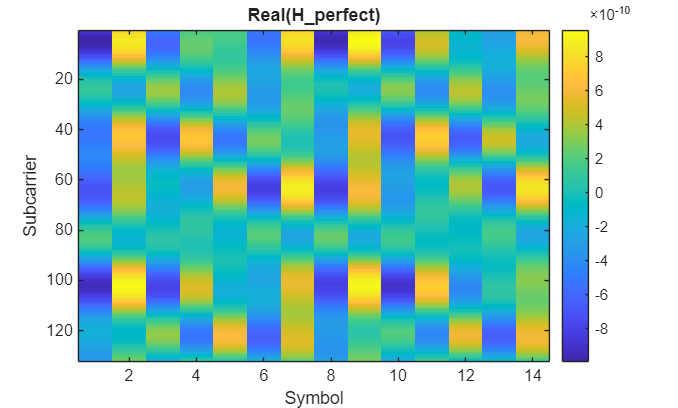

source_li = source_domain.H_li(:,:,1).';
source_ls = source_domain.H_ls(:,:,1).';
source_prac = source_domain.H_prac(:,:,1).';
source_label = source_domain.H_perfect(:,:,1).';
source_ori = source_domain.H_perfect_ori(:,:,1).';

% normalize
% source_label = source_label / max(abs(source_label(:)));
% source_li = source_li / max(abs(source_li(:)));
% source_prac = source_prac / max(abs(source_prac(:)));

figure; imagesc(real(source_ori)); colorbar; title('Real(H\_perfect)')
xlabel('Symbol'); ylabel('Subcarrier');

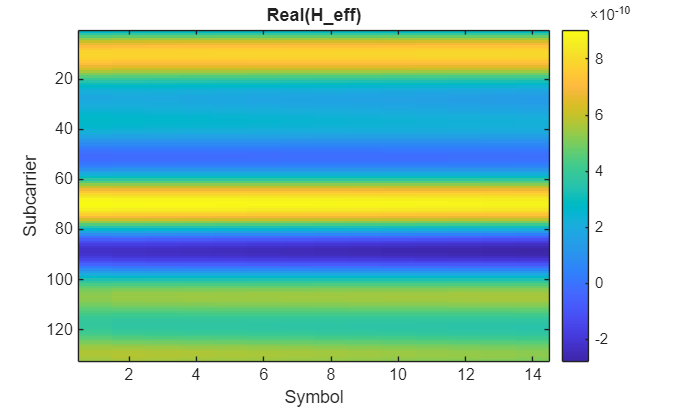


figure; imagesc(real(source_label)); colorbar; title('Real(H\_eff)')
xlabel('Symbol'); ylabel('Subcarrier');

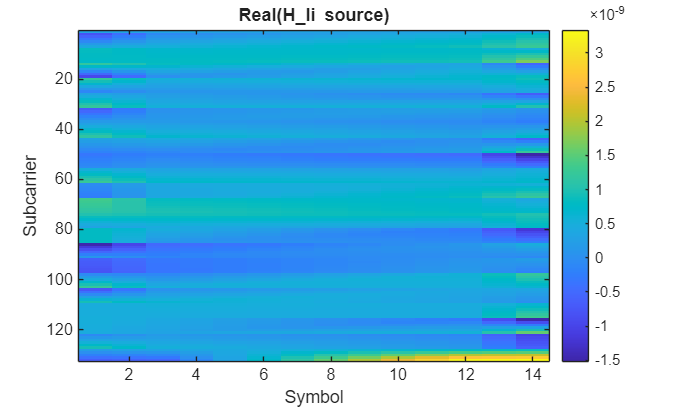


figure;
% subplot(1, 3, 1);
imagesc(real(source_li)); colorbar; title('Real(H\_li source)')
xlabel('Symbol'); ylabel('Subcarrier');


% subplot(1, 3, 2);
% imagesc(real(source_ls)); colorbar; title('Real(H\_ls source)')
% xlabel('Symbol'); ylabel('Subcarrier');
% 
% subplot(1, 3, 3);
% imagesc(real(source_prac)); colorbar; title('Real(H\_prac source)')
% xlabel('Symbol'); ylabel('Subcarrier');

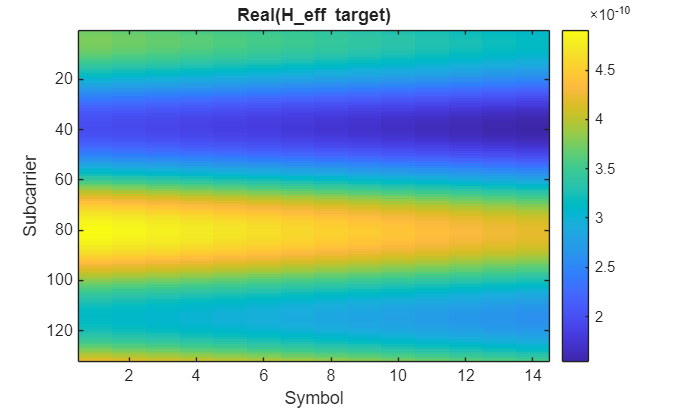

target_li = target_domain.H_li(:,:,2).';
target_ls = target_domain.H_ls(:,:,2).';
target_prac = target_domain.H_prac(:,:,2).';
target_label = target_domain.H_perfect(:,:,2).';

% target_label = target_label / max(abs(target_label(:)));
% target_li = target_li / max(abs(target_li(:)));
% target_ls = target_ls / max(abs(target_ls(:)));
% target_prac = target_prac / max(abs(target_prac(:)));

figure; imagesc(real(target_label)); colorbar; title('Real(H\_eff target)')
xlabel('Symbol'); ylabel('Subcarrier');

figure;
% subplot(1, 3, 1);
imagesc(real(target_li)); colorbar; title('Real(H\_li target)')
xlabel('Symbol'); ylabel('Subcarrier');


% subplot(1, 3, 2);
% imagesc(real(target_ls)); colorbar; title('Real(H\_ls target)')
% xlabel('Symbol'); ylabel('Subcarrier');
% 
% subplot(1, 3, 3);
% imagesc(real(target_prac)); colorbar; title('Real(H\_prac target)')
% xlabel('Symbol'); ylabel('Subcarrier');

source label -> target label

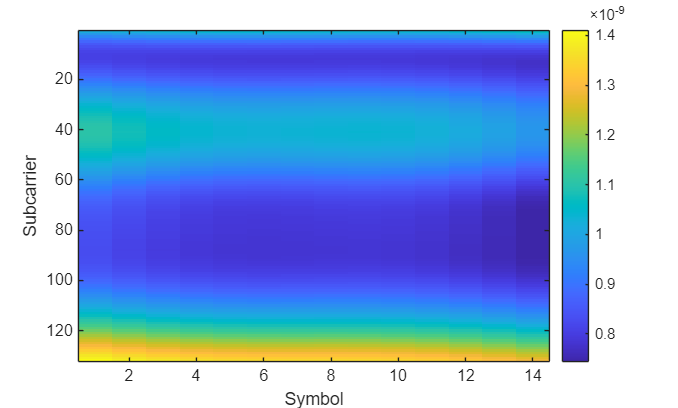

[A_amplitude_spectrum, A_phase_spectrum] = F_extract_DD(source_label);
[B_amplitude_spectrum, B_phase_spectrum] = F_extract_DD(target_label);
% imagesc(A_amplitude_spectrum); colorbar

% imagesc(B_amplitude_spectrum); colorbar
mix_AB = fda_mix_pixels(A_amplitude_spectrum, B_amplitude_spectrum, 3, 3);
    % center: B
    % outer: A
% imagesc(real(mix_AB)); colorbar
fft_mixed = mix_AB .* exp(1i * A_phase_spectrum); % keep phase of A
adapted_image = F_inverse_DD(fft_mixed);
figure
imagesc(abs(adapted_image)); colorbar; 
xlabel('Symbol'); ylabel('Subcarrier')

source label -> target li

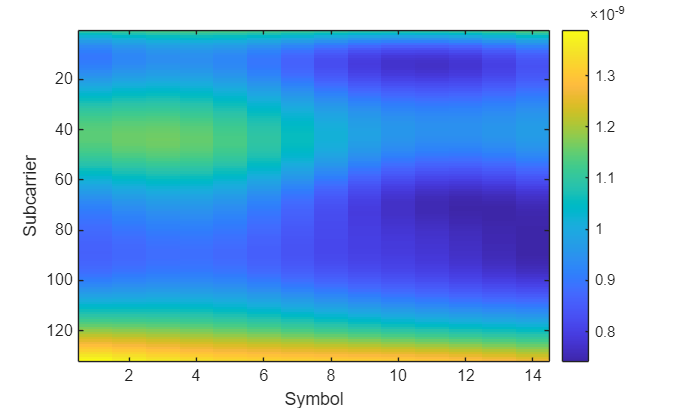

[A_amplitude_spectrum, A_phase_spectrum] = F_extract_DD(source_label);
[B_amplitude_spectrum, B_phase_spectrum] = F_extract_DD(target_li);
% imagesc(A_amplitude_spectrum); colorbar

% imagesc(B_amplitude_spectrum); colorbar
mix_AB = fda_mix_pixels(A_amplitude_spectrum, B_amplitude_spectrum, 3, 3);
    % center: B
    % outer: A
% imagesc(real(mix_AB)); colorbar
fft_mixed = mix_AB .* exp(1i * A_phase_spectrum); % keep phase of A
adapted_image = F_inverse_DD(fft_mixed);
figure
imagesc(abs(adapted_image)); colorbar; 
xlabel('Symbol'); ylabel('Subcarrier')

source li -> target li

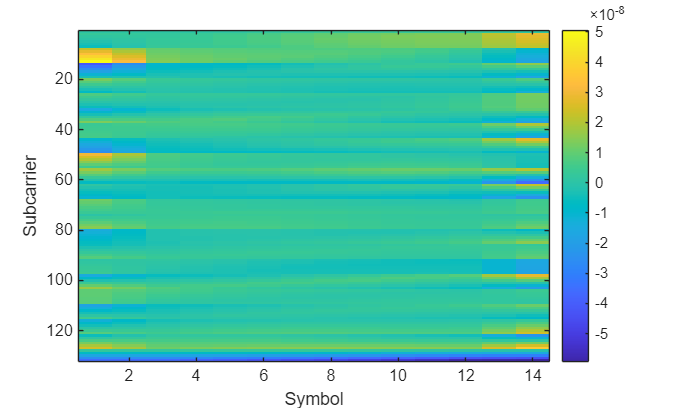

[A_amplitude_spectrum, A_phase_spectrum] = F_extract_DD(source_li);
[B_amplitude_spectrum, B_phase_spectrum] = F_extract_DD(target_li);
% imagesc(A_amplitude_spectrum); colorbar

% imagesc(B_amplitude_spectrum); colorbar
mix_AB = fda_mix_pixels(A_amplitude_spectrum, B_amplitude_spectrum, 7, 3);
    % center: B
    % outer: A
% imagesc(real(mix_AB)); colorbar
fft_mixed = mix_AB .* exp(1i * A_phase_spectrum); % keep phase of A
adapted_image = F_inverse_DD(fft_mixed);
figure
imagesc(real(adapted_image)); colorbar; 
xlabel('Symbol'); ylabel('Subcarrier')